# Bonus Exercise 4: Phased Array Antenna interference nulling over Terrain 

Applicable for both Radar and Communication applications

Number of steps: 6 

Expected completion time: 20 minutes

In this exercise, you will simulate a real-world scenario of **interference nulling using a phased array antenna**. You will model a receive station and multiple transmit sites located within a suburban environment. Antennas will be strategically positioned to achieve line-of-sight (LOS) visibility over challenging intermediate terrain.

Using the power of the **Antenna Toolbox™** and **Phased Array System Toolbox™**, you will:

- Assess the signal strength at the receiver site for the main RF communication link.

- Analyze the impact of interfering signals from other transmit sites.

- Perform **phased array beamforming** using the **Minimum Variance Distortionless Response (MVDR) algorithm** to effectively null out the directions of these interfering signals, demonstrating enhanced communication or radar performance in cluttered environments.

clear
close all

## Create RF Scenario transmit and receive sites 

### Create the RF Receive site

In this step, you will define the main receive site for your simulation. This site will represent an RF antenna, suitable for either a communication link or a radar application. 

Create a receive site object (e.g., using `rxsite`) located in Goffstown, New Hampshire, USA. Show the site in Site Viewer and rotate the view to visualize the site with surrounding terrain.

%--------------------------
% ADD CODE HERE
% Hint: use rxsite object to create Receive site of Antenna Toolbox Site Viewer.
% Type 'doc rxsite' into the command line interface for more information. 
% Supply the "Name","Receive site", "Latitude" value 42.983723 and "Longitude" value -71.587173 as inputs.
% Name the output object 'rx'.  

%---------------------


show(rx)                            % show Rx site using Site Viewer

### Create Transmit Sites: Main Communication Link and Interferers (2.5 GHz Band)

In this step, you will define three transmit sites: one representing your primary RF communication link and two others acting as interference sources. All transmitters will operate in the 2.5 GHz band.

**Create three **`txsite`** objects** and add them to your `siteviewer`. For each site, specify its location (latitude, longitude, and an appropriate antenna height above ground) and assign its transmit power:

- **Main Communication Link: **Location: St. Anselm College (Goffstown, New Hampshire, USA),Transmit Power: 1 Watt

- **Interference Site 1: **Location: Bedford Town Center (Bedford, New Hampshire, USA), Transmit Power: 50 Watts

- **Interference Site 2: **Location: Goffstown Police Department (Goffstown, New Hampshire, USA), Transmit Power: 50 Watts

Verify that all three transmit sites are visible alongside your receive site within the `siteviewer`.

fq = 2.5e9; % Transmit frequency
txBedford = txsite("Name","Interference 1", ...
    "Latitude",42.946193, "Longitude",-71.516234, ...
    "TransmitterPower",50,"TransmitterFrequency",fq);
txStA = txsite("Name","Tx Signal: St. Anselm College", ...
    "Latitude",42.987386, "Longitude",-71.507475,... 
    "TransmitterPower",1, "TransmitterFrequency",fq);
txGPD = txsite("Name","Interference 2", ...
    "Latitude",43.009335, "Longitude",-71.539083, ...
    "TransmitterPower",50,"TransmitterFrequency",fq);
% Place antennas on structures at transmitter sites
txBedford.AntennaHeight = 6;
txStA.AntennaHeight = 6;
txGPD.AntennaHeight = 15;
% set the height of antenna at Receive station  
rx.AntennaHeight = 50;

txs = [txBedford, txStA, txGPD];
show(txs)
show(txStA,Icon='antenna1.png')

## Verify Line-of-Sight (LOS) Link Visibility

A clear line-of-sight path is crucial for optimal radio propagation, especially in environments where direct visibility is desired. In the suburban setting we are modeling, the terrain is the dominant factor influencing LOS visibility. 

Plot these calculated LOS paths within the `siteviewer`.

Plot the line-of-sight propagation paths between the Receive station and transmit sites. The line-of-sight calculation, which currently includes terrain but no other obstacles, should reveal that one of the three transmit sites has an obstructed path to the receive site. Identify which transmit site has this obstruction.

% Display line-of-sight between tx and rx sites
for tx = txs
%--------------------------
% ADD CODE HERE
% Hint: use los object to display line-of-sight in Site Viewer.
% Type 'doc los' into the command line interface for more information. 
% Supply the tx and rx as inputs. 
%---------------------------
    
end


## Specify Receive and Transmit site antennas

### Import Receive Station Antenna Array (8x8 URA)

Import an URA antenna created in Exercise 2 to generate a highly directive beam. Plot the radiation pattern on the map, using the default antenna orientation so that the antenna array is physically oriented in the east direction.

% import URA from Exercise 2 
load ex2_array.mat
rx.Antenna = ura8_8;

% Plot pattern on the map
%--------------------------
% ADD CODE HERE
% Hint: use pattern function to display antenna pattern in Site Viewer.
%  Type 'doc rxsite.pattern' into the command line interface for more information. 
% Supply the Rx site object (rx) and frequency (fq)
%---------------------------------


### Create and Point 4-by-4 Tx Site Antenna Arrays

For each of your transmit sites, define a 4-by-4 Uniform Rectangular Array (URA). These arrays will use a reflector-backed vertical dipole antenna element (refer to the provided helper function for its definition). 

At each transmit site, point the array toward the Receive station and plot the radiation pattern of each steered transmit array on the map within the `siteviewer`. 

txElement = reflectorDipoleElement(fq); % create Tx element
txarray = TxArray(fq,txElement);        % cerate Tx array object 

% Assign array to each transmitter site and point toward Rx station
for tx = txs
    tx.Antenna = txarray;
    tx.AntennaAngle = angle(tx, rx);
    pattern(tx)
end

## Calculate Received Signal Strength (Without Beamforming)

Determine the received signal strength at your receiver from both the main communication link and the interfering transmitters, prior to implementing any beamforming.

Steer the receive antenna towards the main communication link transmitter (St. Anselm College). Calculate the received signal strength (RSSI) at the receive site from *each* transmit site (main link and the two interferers). Use the free space propagation model for these calculations.

steeringVector = phased.SteeringVector("SensorArray",rx.Antenna);

% Compute steering vector for receiver site antenna (steering to Transmit station (txs(2))
[az,el] = angle(rx,txs(2));  % calculate steering direction angles from Rx to Tx
%--------------------------
% ADD CODE HERE
% Hint: use steeringVector object
% Type 'doc steeringVector' into the command line interface for more information. 
% Supply the frequency (fq) and angle [az;el] values
% Name output variable 'sv'

%---------------------------------
    
% Update receive station radiation pattern
rx.Antenna.Taper = conj(sv);
pattern(rx,fq)

for tx = txs
    % Compute signal strength (dBm) using Longley-Rice for multiple transmitters
    ss = sigstrength(rx,tx,"longley-rice");
    disp("Signal strength from " + tx.Name + " Tx:")
    disp(ss + " dBm") 
end

Use Mouse keys to rotate Site Viewer image to visualize main beam and interference directions. Note that interference direction coincide with some Receive antenna sidelobes. 

(Double click on a Receive site to select camera rotation origin)

## Interference Nulling Workflow using MVDR Beamformer

### Generate Receive Array Data

Simulate the received complex baseband (IQ) data across your receive antenna array elements. This data should represent the superposition of the main communication link signal and the two interfering signals as seen by each array element.

ura=rx.Antenna;
ura.Taper=1;
[azd,eld] = angle(rx,txs(2)); % angle of the signal
inputAngle = [azd; eld];  
txi=[txs(1) txs(3)];        % interference angles
[azn,eln] = angle(rx,txi); % angle of the interference

% generate receive signal including the interference for MVDR beamforming (see Helper function)
[rxSignal,rxInt] = mvdr_receive(rx,txs,ura,fq);

### Create MVDR Beamformer object

Create an MVDR beamformer pointing to the target signal direction.

%--------------------------
% ADD CODE HERE
% Hint: use phased.MVDRBeamformer to create a narrowband minimum-variance distortionless-response beamformer 
% Type 'doc phased.MVDRBeamformerr' into the command line interface for more information. 

Signal strength from Interference 1 Tx:


-49.1029 dBm


Signal strength from Tx Signal: St. Anselm College Tx:


-46.4178 dBm


Signal strength from Interference 2 Tx:


-84.9253 dBm


% Supply the Direction (inputAngle) and 'OperatingFrequency' (fq) values,
% and set 'TrainingInputPort'and'WeightsOutputPort' values to 'true'
% Name the output object 'mvdrbeamformer'.
%---------------------------------


### Apply MVDR Beamformer

Finally, apply the MVDR beamformer to the received signal 

%--------------------------
% ADD CODE HERE
% Supply the Received Signal (rxSignal) and Training Data (rxInt) values,
% Name the output 'yURA' and 'w'.
%---------------------------------


You can plot and visualize received signal before and after the beamformer.

### Plot Array Radiation pattern after beamforming

Receive antenna repsonse pattern as a function of azimuth angle (at elevation angles of interferers)

rx.Antenna.Taper =conj(sum(w,2));
figure
set(gcf,'Visible','on')
subplot(2,1,1);
pattern(ura,fq,-180:180,eln(1),'Weights',conj(w),'Type','powerdb',...
    'PropagationSpeed',physconst('LightSpeed'),'Normalize',false,...
    'CoordinateSystem','rectangular');
title("Response Pattern at " + eln(1) + " Degrees Elevation");
axis([-90 90 -70 -30]);
xline(azn,'--r')
subplot(2,1,2);
pattern(ura,fq,-180:180,eln(2),'Weights',conj(w),'Type','powerdb',...
    'PropagationSpeed',physconst('LightSpeed'),'Normalize',false,...
    'CoordinateSystem','rectangular');
axis([-90 90 -70 -30]);
title("Response Pattern at " + eln(2) + " Degrees Elevation");
xline(azn,'--r')

Note that interferers (located at dashed red lines) are supresed. 

## Update Receive station antenna pattern and compute Signal Strength

% Update Receive station antenna pattern
% rx.Antenna.Taper =conj(sum(w,2));
pattern(rx,fq)
% Compute signal strength (dBm) using Longley-Rice for multiple transmitters
for tx = txs
    ss = sigstrength(rx,tx,"longley-rice");
    disp("Signal strength from " + tx.Name + " Tx:")
    disp(ss + " dBm") 
end

Use Mouse keeys to rotate Site Viewer image to visualize that this time interference direction is between Receive antenna sidelobes.

## Bonus step: Receiving 3 signal simultaneously

Assuming that all 3 Tx sites are useful communication links, generate a Rx antenna pattern that can receive all Tx sites simultaneously. The single beam generates radiation lobes toward the three receiver sites. 

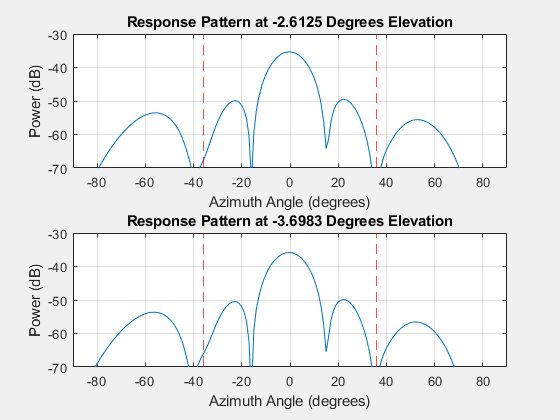

steeringVector = phased.SteeringVector("SensorArray",rx.Antenna);

% Compute steering vector for receive site
[az,el] = angle(txs,rx);
sv = steeringVector(fq,[az el]);

% Update base station radiation pattern
rx.Antenna.Taper = conj(sum(sv,2));
pattern(rx,fq)

% Compute signal strength (dBm)
for tx = txs
    ss = sigstrength(rx,tx,"freespace");
    disp("Signal strength from " + tx.Name + ":")
    disp(ss + " dBm")

end

## Summary

This example demonstrates the integration of a **Phased Array antenna model** within a complex RF scenario. Using the capabilities of the **Antenna Toolbox**, we modeled an RF link over varied terrain, including site and terrain visualization and propagation analysis in a multi-user suburban environment.

The demonstration covers the calculation of **received signal power**, taking the antenna's radiation pattern into account.

Finally, the workflow for a **Minimum Variance Distortionless Response (MVDR) Beamformer** is presented, showcasing its ability to suppress interference effectively. 

## Helper Function for MVDR received signal

### Received signal plus intereference for MVDR workflow 

function [rxSignal,rxInt] = mvdr_receive(rx,txs,ura,fq)
% function generates receive signal (rxSignal) and interference signal
% (rxInt) used for MVDR beamformer

Signal strength from Interference 1 Tx:


-118.636 dBm


Signal strength from Tx Signal: St. Anselm College Tx:


-46.8094 dBm


Signal strength from Interference 2 Tx:


-137.3599 dBm


### Simulate the Received Signal

First, we define the incoming signal. The signal's baseband representation is a simple rectangular pulse as defined below:

t = 0:0.001:0.5;                % Time, sampling frequency is 1kHz
s = zeros(size(t));  
s = s(:);                       % Signal in column vector
s(201:210) = s(201:210) + 1;    % Define the pulse
lambda = physconst("lightspeed")/fq;

Use the collectPlaneWave method of the array object to simulate the received signal at the array. Signal arrives at the array from azd, eld degrees in azimuth and elevation; the received signal can be modeled a

% direction of signal (communication) beam
tx=txs(2);
  [azd,eld] = angle(rx,tx); 

inputAngle = [azd; eld];       
x = collectPlaneWave(ura,s,inputAngle,fq); % signal
%%  uncomment following lines if you would like to visualize workflow graphics 
% figure
% set(gcf,'Visible','on')
% subplot(211)

Signal strength at Interference 1:


-40.8884 dBm


Signal strength at Tx Signal: St. Anselm College:


-47.7491 dBm


Signal strength at Interference 2:


-38.9374 dBm


% plot(t,abs(x(:,1)))
% axis tight
% title('Pulse at Antenna El#1')
% xlabel('Time (s)')
% ylabel('Magnitude (V)')
% subplot(212)
% plot(t,abs(x(:,32)))
% axis tight
% title('Pulse at Antenna El#32')
% xlabel('Time (s)')
% ylabel('Magnitude (V)')

### Add Noise to Received signal

For realistic scenario include some thermal noise to the received signal. The noise can be modeled as complex, Gaussian distributed random numbers. In this exercise, we assume that the noise power is 0.5 watts, which corresponds to a 3 dB signal-to-noise ratio (SNR) at each antenna element.

% Create and reset a local random number generator so the result is the
% same every time.
rs = RandStream.create('mt19937ar','Seed',2008);
noisePwr = .01;   % noise power 
noise = sqrt(noisePwr/2)*(randn(rs,size(x))+1i*randn(rs,size(x)));

The total return is the received signal plus the thermal noise.

### **Add interference signals**

Model two interference signals arriving along the directions azimuth (azn) and elevation (eln) (degrees).

nSamp = length(t);
s1 = 10*randn(rs,nSamp,1);      % intereference 1
s2 = 10*randn(rs,nSamp,1);      % intereference 2
% direction of interference sites
txi=[txs(1) txs(3)];
  [azn,eln] = angle(rx,txi);
% received interference 
interference = collectPlaneWave(ura,[s1 s2],[azn'; eln'],fq);

rxInt = interference + noise;        % total interference + noise
rxSignal = x + rxInt;                % total received signal
end

The total return signal (rxSignal) is 501x64 matrix, where each column corresponds received IQ data for one antenna element. 

function txarray = TxArray(fq,txElement)

% Define array size
ntxrow = 4; ntxcol = 4;  
% Define element spacing
lambda = physconst("lightspeed")/fq;
drow = lambda/2;
dcol = lambda/2;
% Create antenna array
txarray = phased.URA("Size",[ntxrow ntxcol], ...
    "Element",txElement, ...
    "ElementSpacing",[drow dcol]);
end

## Helper function for Transmitter Array element design 

function element = reflectorCrossedDipoleElement(fq, showAntenna)
%reflectorCrossedDipoleElement   Design reflector-backed crossed dipole antenna element

if nargin < 2
    showAntenna = false;
end

lambda = physconst("lightspeed")/fq;
offset = lambda/50;
gndspacing = lambda/4;
gndLength = lambda;
gndWidth = lambda;

% Design crossed dipole elements
d1 = design(dipole,fq);
d1.Tilt = [90,-45];
d1.TiltAxis = ["y","z"];
d2 = copy(d1);
d2.Tilt = 45;
d2.TiltAxis = "x";

% Design reflector
r = design(reflector,fq);
r.Exciter = d1;
r.GroundPlaneLength = gndLength;
r.GroundPlaneWidth = gndWidth;
r.Spacing = gndspacing;
r.Tilt = 90;
r.TiltAxis = "y";
if showAntenna
    show(r)
end

% Form the crossed dipole backed by reflector
refarray = conformalArray;
refarray.ElementPosition(1,:) = [gndspacing 0 0];
refarray.ElementPosition(2,:) = [gndspacing+offset 0 0];
refarray.Element = {r, d2};
refarray.Reference = "feed";
refarray.PhaseShift = [0 90];
if showAntenna
    show(refarray);
    view(65,20)
end

% Create custom antenna element from pattern
[g,az,el] = pattern(refarray,fq);
element = phased.CustomAntennaElement;
element.AzimuthAngles = az;
element.ElevationAngles = el;
element.MagnitudePattern = g;
element.PhasePattern = zeros(size(g));
end

function element = reflectorDipoleElement(fq)
%reflectorDipoleElement   Design reflector-backed dipole antenna element

% Design reflector and exciter, which is vertical dipole by default
element = design(reflector,fq);
element.Exciter = design(element.Exciter,fq);

% Tilt antenna element to radiate in xy-plane, with boresight along x-axis
element.Tilt = 90;
element.TiltAxis = "y";
element.Exciter.Tilt = 90;
element.Exciter.TiltAxis = "y";
end